# Seeding the random number generation

rng(1)
N=1000-200;%-100*2; % Length of the data
txname='tx_x13_nonormal.dat';

## Generate complex white noise pulses TX Data

dat=(sign(randn(N,1))+1i*sign(randn(N,1)));%*(1/sqrt(2));
negative = -1*ones(100,1)-1i*ones(100,1);
positive = 1*ones(100,1)+1i*ones(100,1);
dat= [negative.' dat.' positive.'].'

dat =   -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i
  -1.0000 - 1.0000i


x_us=upsample(dat,100);
pulse=ones(100,1);
x=conv(x_us,pulse);

write_usrp_data_file(x,txname)

a=[1;2;3];
b=[4;5;6;7];
c=[a' b']';

## Generate a cosine

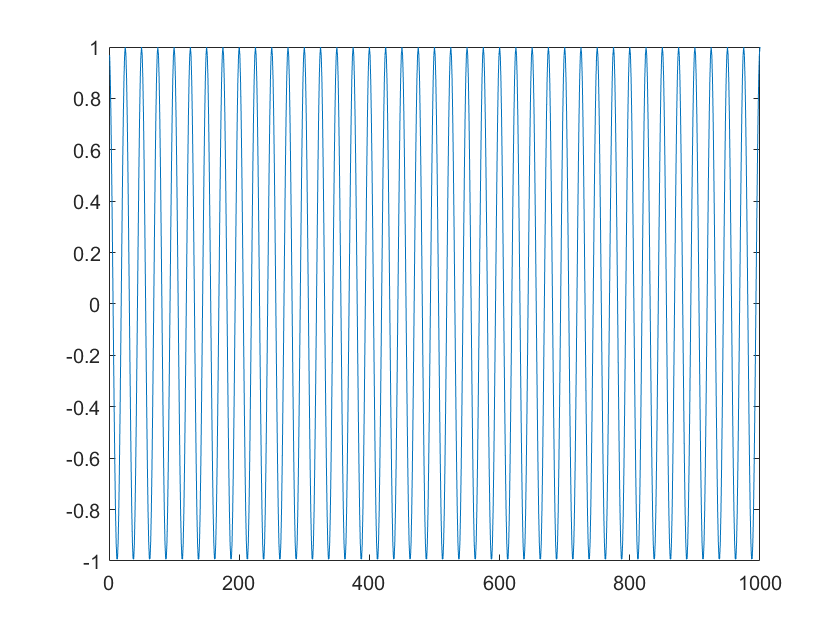

x=1:N;
cos_Dat=cos(2*pi/25*x);
write_usrp_data_file(cos_Dat)
plot(cos_Dat)


%write_usrp_data_file(x,txname)

err_rate = 0.4370